clear; clc;
addpath(genpath("MATLAB"));
addpath(genpath("weather"));
addpath(genpath("haars_data"));

parent_dir = "haars_data";
drop_dir = "DN149_Lt1_n12_08052025_side";
full_dir = fullfile(parent_dir, drop_dir);

%% Run Data
data_out = get_flight_estimates(full_dir);

1 / 31912 (t=6296.988000)
2 / 31912 (t=6297.063000)
3 / 31912 (t=6297.138000)
4 / 31912 (t=6297.213000)
5 / 31912 (t=6297.288000)
6 / 31912 (t=6297.363000)
7 / 31912 (t=6297.438000)
8 / 31912 (t=6297.513000)
9 / 31912 (t=6297.588000)
10 / 31912 (t=6297.663000)
11 / 31912 (t=6297.738000)
12 / 31912 (t=6297.813000)
13 / 31912 (t=6297.888000)
14 / 31912 (t=6297.963000)
15 / 31912 (t=6298.038000)
16 / 31912 (t=6298.113000)
17 / 31912 (t=6298.188000)
18 / 31912 (t=6298.263000)
19 / 31912 (t=6298.338000)
20 / 31912 (t=6298.413000)
21 / 31912 (t=6298.488000)
22 / 31912 (t=6298.563000)
23 / 31912 (t=6298.638000)
24 / 31912 (t=6298.713000)
25 / 31912 (t=6298.788000)
26 / 31912 (t=6298.863000)
27 / 31912 (t=6298.938000)
28 / 31912 (t=6299.013000)
29 / 31912 (t=6299.088000)
30 / 31912 (t=6299.163000)
31 / 31912 (t=6299.238000)
32 / 31912 (t=6299.313000)
33 / 31912 (t=6299.388000)
34 / 31912 (t=6299.463000)
35 / 31912 (t=6299.538000)
36 / 31912 (t=6299.613000)
37 / 31912 (t=6299.688000)
38 / 31912


carp_data = data_out.carp;

% Number of simulations
num_sims = 1;

all_results = cell(num_sims, 1);

for i = 1:num_sims
    all_results{i} = Carp_Estimator('carp_data',carp_data);
    
   
    if mod(i, 10) == 0
        fprintf('Completed %d/%d simulations\n', i, num_sims);
    end
end



disp('Results structure:');

Results structure:


disp(all_results{1});

                      carp: [1×1 struct]
                propagator: [1×1 struct]
                time_error: 10.6074
        displacement_error: 5.5706e+03
    displacement_error_pct: 911.7828
        descent_rate_error: -8.5354
    descent_rate_error_pct: -47.2157



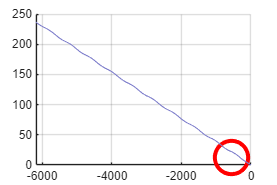


% Create 3D plot
figure('Position', [100, 100, 1200, 800]);
hold on;
grid on;

% Plot all drop trajectories
for i = 1:num_sims
    traj = all_results{i}.propagator.trajectory;
    plot3(traj(:,1), traj(:,2), traj(:,3), ...
          'Color', [0.5 0.5 0.8 0.3], 'LineWidth', 0.8);
end

% Plot CARP position (release point)
carp = all_results{1}.carp;
ftd_meters = carp.ftd * 0.9144;  % yards to meters
carp_east = ftd_meters * sind(carp_data.heading);
carp_north = ftd_meters * cosd(carp_data.heading);
carp_alt = carp_data.altitude * 0.3048;  % feet to meters

plot3(carp_east, carp_north, 0, ...
      'ro', 'MarkerSize', 25, 'LineWidth', 3, 'DisplayName', 'CARP Landing Point');


plot3(carp_data.altitude(1), carp_data.altitude(2), carp_data.altitude(3), 'mo', 'MarkerSize', 25, 'DisplayName', 'Actual Landing Point');

Index exceeds the number of array elements. Index must not exceed 1.


% Plot all impact points
for i = 1:num_sims
    final_pos = all_results{i}.propagator.trajectory(end, :);
    plot3(final_pos(1), final_pos(2), final_pos(3), ...
          'b.', 'MarkerSize', 10);
end

xlabel('East [m]');
ylabel('North [m]');
zlabel('Altitude [m]');
title(sprintf('%d Airdrop Simulations with CARP Estimate', num_sims));
legend('Trajectories', 'CARP Landing Point', 'Impact Points', 'Location', 'best');
view(45, 30);
hold off;

% Calculate impact statistics
all_impacts = zeros(num_sims, 3);
for i = 1:num_sims
    all_impacts(i, :) = all_results{i}.propagator.trajectory(end, :);
end
